## Artifical Neural Network for thermogravimetric data analysis

This Live Script is intend to present the capabilities and accuracy of Artificial Neural Network (ANN) trained to recognize biomass composition basing on thermogravimetric data

### Reference data for ANN

The input data consist of both kinetic parameters from Coast-Redfern TGA analysis, as well as measured content of cellulose, hemicellulose and lignin in the 62 samples. Heating rate is denoted in K/s, activation energy (Ea) in kJ/mol, pre-exponential factor (A) in s^-1. Reaction order is dimensionless.

clear all
load Input_data.mat
disp(Input_data)

    No1                 Biomass                 HeatingRate        A           Ea        n      Cellulose    Hemicellulose    Lignin
    ___    _________________________________    ___________    __________    ______    _____    _________    _____________    ______
     1     Pine sawdust                               5          1.34e+10    116.12     3.28      55.92          15.35        10.55 
     2     Pine sawdust                              10          2.83e+05     67.97     2.04      55.92          15.35        10.55 
     3     Pine sawdust                              15             82100     62.11     2.48      55.92          15.35        10.55 
     4     Pine sawdust      

### Loading of trained ANN

The ANN was already trained over presented data and is available as a MATLAB structure that can be freely loaded and tested in this environment.

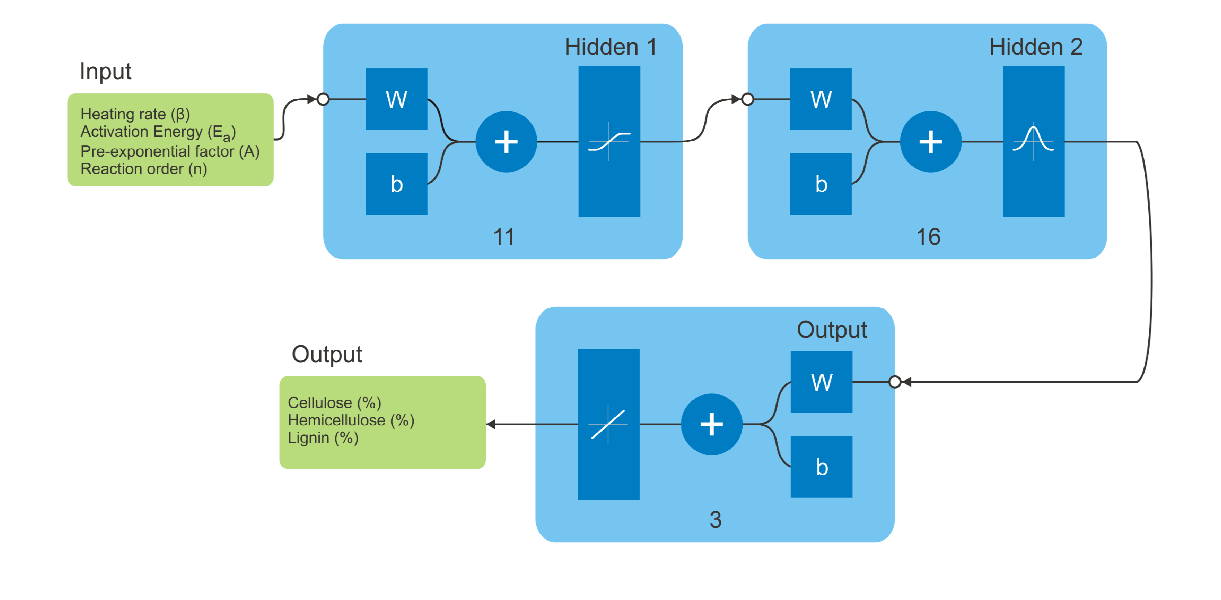

load ANN_trained.mat
imshow(imread("ANN_topology.png"))

### ANN benchmark

input=[Input_data.HeatingRate, Input_data.A, Input_data.Ea, Input_data.n]';
target=[Input_data.Cellulose, Input_data.Hemicellulose, Input_data.Lignin]';
output=net(input);
RPD=mean(mean(abs(target-output)./((abs(target)+abs(output))/2)))*100;
fprintf("Relative Percentage Difference = %2.2f",RPD);

Relative Percentage Difference = 17.66

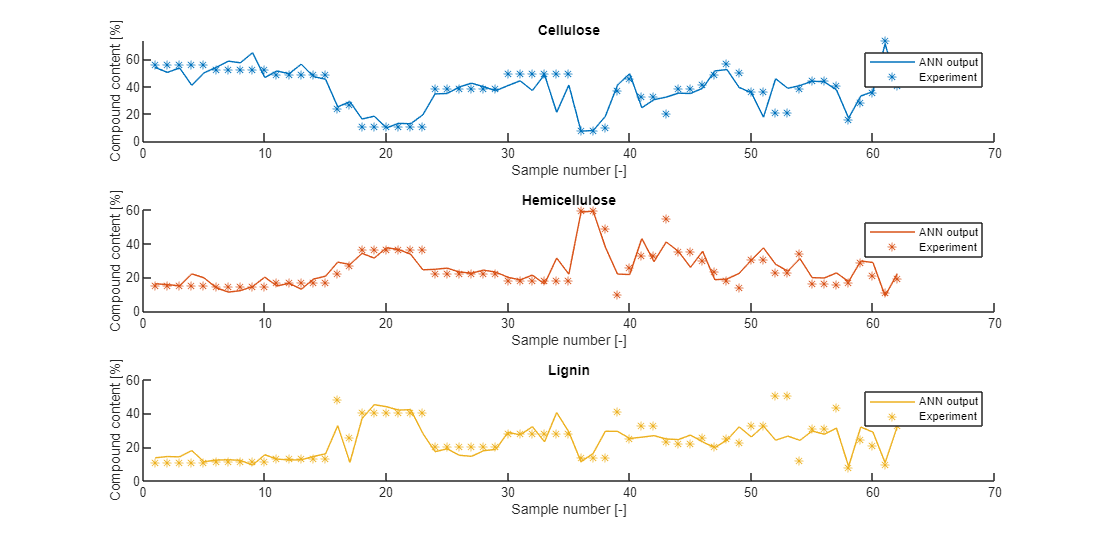

tiledlayout(3,1)
nexttile
hold on
plot(output(1,:),   'Color','#0072BD');
plot(target(1,:),"*", 'Color','#0072BD');
legend('ANN output','Experiment');
title('Cellulose')
xlabel('Sample number [-]')
ylabel('Compound content [%]')
hold off
nexttile
hold on
plot(output(2,:),   'Color','#D95319');
plot(target(2,:),"*", 'Color','#D95319');
legend('ANN output','Experiment');
title('Hemicellulose')
xlabel('Sample number [-]')
ylabel('Compound content [%]')
hold off
nexttile
hold on
plot(output(3,:),   'Color','#EDB120');
plot(target(3,:),"*", 'Color','#EDB120');
legend('ANN output','Experiment');
title('Lignin')
xlabel('Sample number [-]')
ylabel('Compound content [%]')
hold off